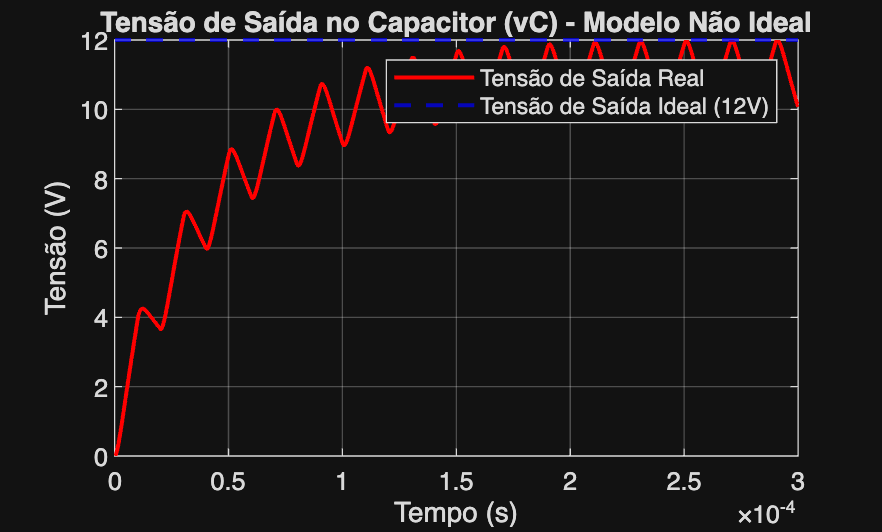

% Parâmetros do Projeto
Vi = 24;      % Tensão de entrada (V)
f = 50e3;     % Frequência de chaveamento (Hz)
D = 0.5;      % Razão Cíclica

% Valores dos Componentes do Exemplo 3
R = 6;        % Resistor (Ohms)
L = 300e-6;   % Indutor (H)
C = 215e-9;   % Capacitor (F)

% Parâmetros das Não Idealidades
R_DSon = 0.18; % Resistência do MOSFET IRF640
r_L = 0.5;     % Resistência série do indutor
r_D = 0.04;    % Resistência série do diodo MUR640

% Matrizes de estado (numéricas)
A1 = [-(R_DSon + r_L)/L, -1/L; 1/C, -1/(R*C)];
B1 = [1/L; 0];
A2 = [-(r_D + r_L)/L, -1/L; 1/C, -1/(R*C)];
B2 = [0; 0];

% Configuração da Simulação
Dt = 1e-7;
t_max = 3e-4;
t = 0:Dt:t_max;

% Sinal PWM
PWM = 0.5 + 0.5 * square(2 * pi * f * t, D * 100);

% Laço de Simulação
iL = zeros(1, length(t));
vC = zeros(1, length(t));
Xo = [0; 0];

for k = 2:length(t)
    if PWM(k-1) > 0.5
        X = (A1 * Xo + B1 * Vi) * Dt + Xo;
    else
        X = (A2 * Xo + B2 * Vi) * Dt + Xo;
    end
    iL(k) = X(1);
    vC(k) = X(2);
    Xo = X;
end

% Plotagem do resultado
figure;
plot(t, vC, 'r', 'LineWidth', 1.5);
hold on;
yline(12, 'b--', 'LineWidth', 1.5); % Linha da tensão de saída ideal
title('Tensão de Saída no Capacitor (vC) - Modelo Não Ideal');
xlabel('Tempo (s)');
ylabel('Tensão (V)');
legend('Tensão de Saída Real', 'Tensão de Saída Ideal (12V)');
grid on;